%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% LOAD CORRESPONDING_POINTS, FRAME_INDEX_PAIRS, DIM_AND_CROP, VIDEOS %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

session = 's02_Session_3';

%% FOR CAROLINE_SESSION_1: -3, FOR CAROLINE_SESSION_2: -3, FOR CAROLINE_SESSION_3: 0, FOR CAROLINE_SESSION_4: 0
%% FOR CAROLINE_SESSION_5: -1, FOR CAROLINE_SESSION_6: -1, FOR HANNA_SESSION_1: -1, FOR HANNA_SESSION_2: 1
%% FOR HANNA_SESSION_3: 0, FOR HANNA_SESSION_4: 2, FOR HANNA_SESSION_7: 2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
frames_sync_diff = 0; %%%%%%%%% EDIT THIS FOR EACH SESSION %%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

video1 = 's02_front_s3_20210411_fps_sync';
video2 = 's02_side_s3_20210411_fps_sync';
inputs_path = '/Users/jiyangli/Documents/UB/research/SmartRing/datasets/video_asl/inputs';
results_path = '/Users/jiyangli/Documents/UB/research/SmartRing/datasets/video_asl/results';
codes_path = '/Users/jiyangli/Documents/UB/research/SmartRing/asl_3d_handjoint_coordinates';

filename = strcat(results_path, '/', session, '/corresponding_points.txt');
[A, ~]=importdata(filename);
corresponding_coordinates = reshape(A, [168,size(A,2)/168])';

filename2 = strcat(results_path, '/', session, '/frame_index_pairs.txt');
[B, ~]=importdata(filename2);
keypoint_index_pairs = reshape(B, [2,size(B,2)/2])';

filename3 = strcat(results_path, '/', session, '/', video1, '/dim_and_crop.txt');
[C, ~]=importdata(filename3);

filename4 = strcat(results_path, '/', session, '/', video2, '/dim_and_crop.txt');
[D, ~]=importdata(filename4);

v1 = VideoReader(strcat(inputs_path, '/asl_ours/', session, '/', video1, '.mp4'));
v2 = VideoReader(strcat(inputs_path, '/asl_ours/', session, '/', video2, '.mp4'));
v1.NumFrames
v2.NumFrames

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% SET INTRINSIC PARAMETERS, CALCULATE AND SAVE FUNDAMENTAL MATRIX %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% set num_of_frames to size(keypoint_index_pairs, 1) if you want to get the
% 3d keypoints of all the frames of the video. Otherwise, set it to any
% other number.

num_of_frames = size(keypoint_index_pairs, 1)
num_of_frames_for_fmatrix = 300;
fMatrix = zeros([3,3]);
F_list = zeros([3,3,num_of_frames_for_fmatrix]);
num_of_useful_f = 0;
inliersincorrect = 0;
inliers_list = zeros([num_of_frames_for_fmatrix,2]);

% relative focal length
f = 450;

IntrinsicMatrix = [f 0 0;...
                   0 f 0;...
                   C(2)/2 C(1)/2 1];

radialDistortion = [0 0]; 
camera_params = cameraParameters('IntrinsicMatrix',IntrinsicMatrix,'RadialDistortion',radialDistortion);

parfor i = 1:num_of_frames_for_fmatrix
    
    if frames_sync_diff >= 0
        I1 = read(v1, keypoint_index_pairs(i, 2) + frames_sync_diff);
        I2 = read(v2, keypoint_index_pairs(i, 2));
    else
        I1 = read(v1, keypoint_index_pairs(i,2));
        I2 = read(v2, keypoint_index_pairs(i,2) - frames_sync_diff);
    end
    
    imagePoints1 = detectMinEigenFeatures(im2gray(I1), 'MinQuality', 0.01);
    tracker = vision.PointTracker('MaxBidirectionalError', 1, 'NumPyramidLevels', 5, 'MaxIterations', 300);
    
    imagePoints1 = imagePoints1.Location;
    initialize(tracker, imagePoints1, I1);
    
    [imagePoints2, validIdx] = step(tracker, I2);
    matchedPoints1 = imagePoints1(validIdx, :);
    matchedPoints2 = imagePoints2(validIdx, :);
    
    selection = matchedPoints1(:,1) >= C(2)-C(6) & matchedPoints1(:,1) <= C(2)-C(5) & matchedPoints1(:,2) >= C(3) & matchedPoints1(:,2) <= C(4)...
        & matchedPoints2(:,1) >= D(2)-D(6) & matchedPoints2(:,1) <= D(2)-D(5) & matchedPoints2(:,2) >= D(3) & matchedPoints2(:,2) <= D(4);
    
    sum(selection)
    
    matchedPoints1 = matchedPoints1(selection, :);
    matchedPoints2 = matchedPoints2(selection, :);
    
    matchedPoints1_all = zeros([42 + size(matchedPoints1, 1),2]);
    matchedPoints2_all = zeros([42 + size(matchedPoints2, 1),2]);
    
    for j = 1:size(corresponding_coordinates, 2)
        
        if mod(j, 4) == 1
            matchedPoints1_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
            
        elseif mod(j, 4) == 2
            matchedPoints1_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
        
        elseif mod(j, 4) == 3
            matchedPoints2_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
            
        else
            matchedPoints2_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
            
        end
        
    end
    
    matchedPoints1_all(43:end,:) = matchedPoints1;
    matchedPoints2_all(43:end,:) = matchedPoints2;

    % most time consuming function. Reduce NumTrials to get faster, less
    % accurate results
    
    [fMatrix, epipolarInliers] = estimateFundamentalMatrix(...
      matchedPoints1_all, matchedPoints2_all, 'Method', 'MSAC', 'NumTrials', 1000000);

%     LEAVE THIS COMMENTED
%     temp1 = matchedPoints1_all;
%     temp1(:,3) = ones([size(matchedPoints1_all, 1), 1]);
%     
%     temp2 = matchedPoints2_all; 
%     temp2(:,3) = ones([size(matchedPoints2_all, 1), 1]);
%     temp2 = temp2';
%     
%     num_of_inliers = 0;
%     
%     for k=1:size(matchedPoints1_all, 1)
%         
%         u = temp1(k,:);
%         v = temp2(:,k);
%         
%         a = fMatrix*v;
%         b = u*fMatrix;
%         
% %         temp = ((u*fMatrix*v)^2) * ( (1/norm(a(1:2,:))^2) + (1/norm(b(:,1:2))^2) )  %% SAMPSON DISTANCE CALCULATION
%         temp = (u*fMatrix*v)^2
%         
%         if temp <= 0.01 && temp >= -0.01
%             num_of_inliers = num_of_inliers + 1;
%         end
%         
%     end
%     
%     if num_of_inliers ~= sum(epipolarInliers)
%         inliersincorrect = inliersincorrect + 1; 
%     end
%     
%     inliers_list(i,:) = [num_of_inliers, sum(epipolarInliers)];
    sum(epipolarInliers)

    inlierPoints1 = matchedPoints1_all(epipolarInliers, :);
    inlierPoints2 = matchedPoints2_all(epipolarInliers, :);
    
    [~, ~, num] = relativeCameraPose(fMatrix, camera_params, inlierPoints1, inlierPoints2);
    
    if num == 1
        F_list(:,:,i) = fMatrix;
        num_of_useful_f = num_of_useful_f + 1;
    end
    
    if mod(i,1) == 0
        i
    end

end

parfor i=1:3
    
    for j=1:3
        
        F_ij = F_list(i,j,:);
        F_ij = F_ij(1,1,F_ij ~= 0);
        F_ij = sort(F_ij);
        outliers_on_both_sides = cast(size(F_ij,3)/5, 'int32');
        F_ij = F_ij(1,1,outliers_on_both_sides+1:size(F_ij,3)-outliers_on_both_sides);
        fMatrix(i,j) = mean(F_ij, 3);
        
    end
    
end

num_of_useful_f
fMatrix


path = strcat(results_path, '/', session, '/fundamental');
if ~exist(path, 'dir')
    mkdir(path)
end
% if isfolder(path) == 0
%     [status, msg, msgID] = mkdir(path)
% end

file = strcat(path, '/f', string(f), '.txt');
fileID = fopen(file,'w');
fprintf(fileID,'%6.12f %6.12f %6.12f\n',(fMatrix)');
fclose(fileID);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% ESTIMATE RELATIVE CAMERA POSE, GENERATE 3D POSE, ESTIMATE BONE 10-11 LENGTH %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

filename = strcat(results_path, '/', session, '/fundamental', '/f', string(f), '.txt');
[fMatrix, ~] = importdata(filename);
fMatrix

R_list = zeros(3,3,5);
R_counts = zeros(1,1,5);
R_distinct = 0;
R_list_full = zeros(3,3,5);

t_list = zeros(1,3,5);
t_counts = zeros(1,1,5);
t_distinct = 0;
t_list_full = zeros(1,3,5);

for i=1:5

    frame_idx = randi(num_of_frames, 1);
    if frames_sync_diff >= 0
        I1 = read(v1, keypoint_index_pairs(frame_idx, 2) + frames_sync_diff);
        I2 = read(v2, keypoint_index_pairs(frame_idx, 2));
    else
        I1 = read(v1, keypoint_index_pairs(frame_idx,2));
        I2 = read(v2, keypoint_index_pairs(frame_idx,2) - frames_sync_diff);
    end
    
    imshowpair(I1, I2, 'montage'); 
    
    imagePoints1 = detectMinEigenFeatures(im2gray(I1), 'MinQuality', 0.01);
    
    tracker = vision.PointTracker('MaxBidirectionalError', 1, 'NumPyramidLevels', 5, 'MaxIterations', 300);
    
    imagePoints1 = imagePoints1.Location;
    initialize(tracker, imagePoints1, I1);
    
    [imagePoints2, validIdx] = step(tracker, I2);
    matchedPoints1 = imagePoints1(validIdx, :);
    matchedPoints2 = imagePoints2(validIdx, :);
    
    selection = matchedPoints1(:,1) >= C(2)-C(6) & matchedPoints1(:,1) <= C(2)-C(5) & matchedPoints1(:,2) >= C(3) & matchedPoints1(:,2) <= C(4)...
        & matchedPoints2(:,1) >= D(2)-D(6) & matchedPoints2(:,1) <= D(2)-D(5) & matchedPoints2(:,2) >= D(3) & matchedPoints2(:,2) <= D(4);
    
    sum(selection)
    
    matchedPoints1 = matchedPoints1(selection, :);
    matchedPoints2 = matchedPoints2(selection, :);
    
    matchedPoints1_all = zeros([42 + size(matchedPoints1, 1),2]);
    matchedPoints2_all = zeros([42 + size(matchedPoints2, 1),2]);
    
    for j = 1:size(corresponding_coordinates, 2)
        
        if mod(j, 4) == 1
            matchedPoints1_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(frame_idx,j);
            
        elseif mod(j, 4) == 2
            matchedPoints1_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(frame_idx,j);
        
        elseif mod(j, 4) == 3
            matchedPoints2_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(frame_idx,j);
            
        else
            matchedPoints2_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(frame_idx,j);
            
        end
        
    end
    
    matchedPoints1_all(43:end,:) = matchedPoints1;
    matchedPoints2_all(43:end,:) = matchedPoints2;
    
    % most time consuming function. Reduce NumTrials to get faster, less
    % accurate results
    
    [~, epipolarInliers] = estimateFundamentalMatrix(...
      matchedPoints1_all, matchedPoints2_all, 'Method', 'MSAC', 'NumTrials', 1000000);
    
    sum(epipolarInliers)
    
    inlierPoints1 = matchedPoints1_all(epipolarInliers, :);
    inlierPoints2 = matchedPoints2_all(epipolarInliers, :);
    
    [R, t, num] = relativeCameraPose(fMatrix, camera_params, inlierPoints1, inlierPoints2);
    
    R_list_full(:,:,i) = R;
    t_list_full(:,:,i) = t;
    
    flag1 = 0;
    flag2 = 0;
    
    for j=1:R_distinct
        
        if R == R_list(:,:,j)
            R_counts(1,1,j) = R_counts(1,1,j) + 1;
            flag1 = 1;
            break;
        end
        
    end
    
    if flag1 == 0
        R_distinct = R_distinct + 1;
        R_list(:,:,R_distinct) = R;
        R_counts(1,1,R_distinct) = 1;
    end
    
    for j=1:t_distinct
        
        if t == t_list(:,:,j)
            t_counts(1,1,j) = t_counts(1,1,j) + 1;
            flag2 = 1;
            break;
        end
        
    end
    
    if flag2 == 0
        t_distinct = t_distinct + 1;
        t_list(:,:,t_distinct) = t;
        t_counts(1,1,t_distinct) = 1;
    end

end

[~, idx] = max(R_counts);
R = R_list(:,:,idx);

[~, idx] = max(t_counts);
t = t_list(:,:,idx);
    
X0_list = zeros([2,3,num_of_frames]);
bone_length = 0;
coords_all = zeros([42,3,num_of_frames]);

camMatrix1 = cameraMatrix(camera_params, eye(3), [0 0 0]);
camMatrix2 = cameraMatrix(camera_params, R', -t*R');

for i = 1:num_of_frames

    matchedPoints1 = zeros([42,2]);
    matchedPoints2 = zeros([42,2]);
    
    for j = 1:size(corresponding_coordinates, 2)
        
        if mod(j, 4) == 1
            
            matchedPoints1(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
            
        elseif mod(j, 4) == 2
            
            matchedPoints1(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
        
        elseif mod(j, 4) == 3
            
            matchedPoints2(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
            
        else

            matchedPoints2(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
            
        end
        
    end
    
    points3D = triangulate(matchedPoints1, matchedPoints2, camMatrix1, camMatrix2);

    coords_all(:,:,i) = points3D;
    
    X0_1 = coords_all(1,:,i);
    X0_2 = coords_all(22,:,i);
    X0_list(:,:,i) = [X0_1; X0_2];
    
%     d1 = sqrt(sum((coords_all(10,:,i) - coords_all(11,:,i)) .^ 2));
%     d2 = sqrt(sum((coords_all(31,:,i) - coords_all(32,:,i)) .^ 2));
    d1 = sqrt(sum((coords_all(1,:,i) - coords_all(10,:,i)) .^ 2));
    d2 = sqrt(sum((coords_all(22,:,i) - coords_all(31,:,i)) .^ 2));
    bone_length = bone_length + d1 + d2;
    
end

bone_length = bone_length/(2*num_of_frames)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% SAVE 3D KEYPOINTS WITH OPTION TO SCALE OR NOT SCALE %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% mode = 'no scaling' means raw 3d results will be saved.
% mode = 'scaling' means raw 3d results will first be scale normalised with
% the bone connecting joints 10 and 11, and then saved.

% mode = 'no scaling'
mode = 'scaling'

% FOR MODE2, WE NEED TO VISUALLY CHECK WHICH ONE PRODUCES BETTER 3D POSE
mode2 = 'average'
% mode2 = 'per frame'

for i = 1:num_of_frames
    
    if strcmp(mode, 'no scaling') == true
        
        path = strcat(results_path, '/', session, '/3d_keypoints_450');
        if isfolder(path) == 0
            [status, msg, msgID] = mkdir(path)
        end
        path = strcat(path, '/', string(i), '.txt');
        fileID = fopen(path,'w');
        fprintf(fileID,'%6.4f %6.4f %6.4f\n',(coords_all(:,:,i))');
        fclose(fileID);
        
    elseif strcmp(mode, 'scaling') == true
        
        coords_all(1:21,:,i) = coords_all(1:21,:,i) - coords_all(1,:,i);
        coords_all(22:end,:,i) = coords_all(22:end,:,i) - coords_all(22,:,i);
        
%         d1 = sqrt(sum((coords_all(10,:,i) - coords_all(11,:,i)) .^ 2));
%         d2 = sqrt(sum((coords_all(31,:,i) - coords_all(32,:,i)) .^ 2));
        d1 = sqrt(sum((coords_all(1,:,i) - coords_all(10,:,i)) .^ 2));
        d2 = sqrt(sum((coords_all(22,:,i) - coords_all(31,:,i)) .^ 2));
        
        coords_all(1:21,:,i) = coords_all(1:21,:,i)/d1 ;
        coords_all(22:end,:,i) = coords_all(22:end,:,i)/d2 ;
        
        roots_mid_point = ( X0_list(1,:,i) + X0_list(2,:,i) )/2;
        
        roots_distance = sqrt(sum((X0_list(1,:,i) - X0_list(2,:,i)) .^ 2));
        
        if strcmp(mode2, 'per frame') == true
            
           bone_length = (d1 + d2)/2; 
           
        end
        
        p1 = roots_mid_point + ( X0_list(1,:,i) - X0_list(2,:,i) ) / (bone_length*2);
        p2 = roots_mid_point + ( X0_list(2,:,i) - X0_list(1,:,i) ) / (bone_length*2);
        
        coords_all(1:21,:,i) = coords_all(1:21,:,i) + p1;
        coords_all(22:end,:,i) = coords_all(22:end,:,i) + p2;
        
        path = strcat(results_path, '/', session, '/3d_keypoints_450_scaled');
        if isfolder(path) == 0
            [status, msg, msgID] = mkdir(path)
        end
        path = strcat(path, '/', string(i), '.txt');
        fileID = fopen(path,'w');
        fprintf(fileID,'%6.4f %6.4f %6.4f\n',(coords_all(:,:,i))');
        fclose(fileID);
        
    end
    
end

% inliersincorrect
% inliers_list
R_counts

R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts

t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


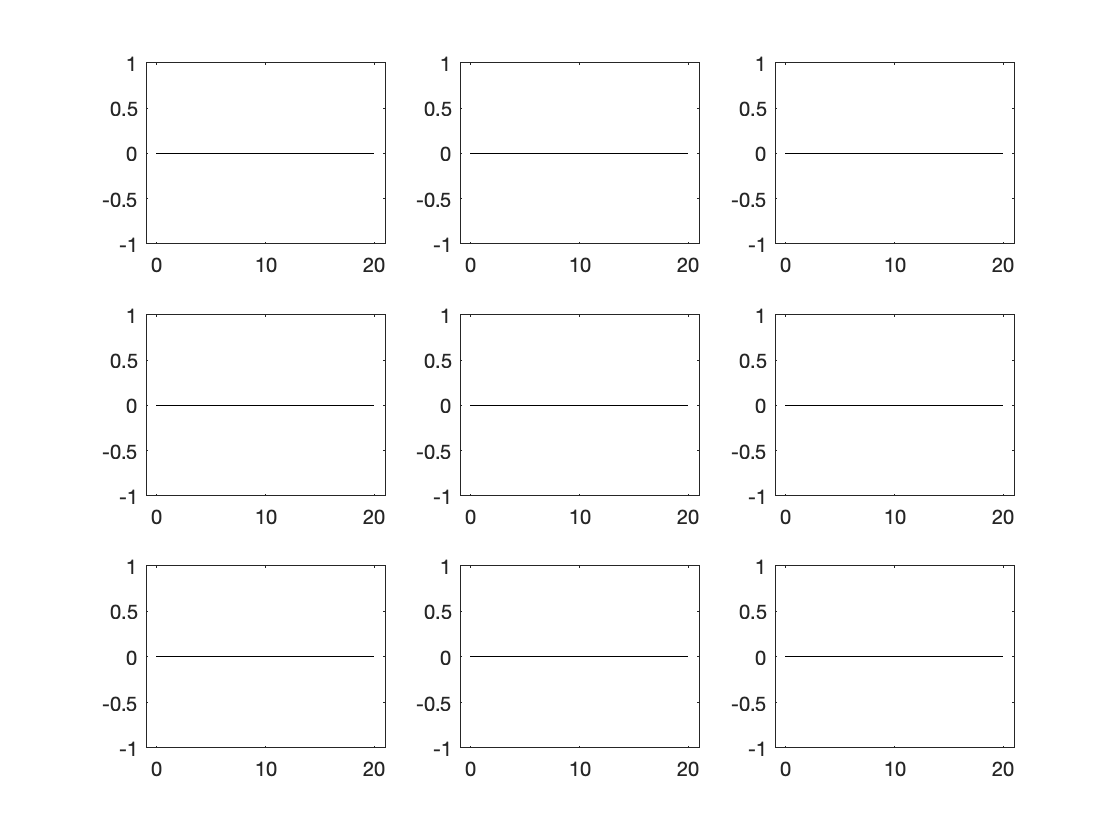

figure;

for i=1:3
    
    for j=1:3
        
        F_ij = F_list(i,j,:);
        F_ij = F_ij(1,1,F_ij ~= 0);
        subplot(3, 3, 3*(i-1)+j);
        histogram(F_ij, 20);
        
    end
    
end

figure;

for i=1:3
    
    for j=1:3
        
        F_ij = F_list(i,j,:);
        F_ij = F_ij(1,1,F_ij ~= 0);
        F_ij = sort(F_ij);
        outliers_on_both_sides = cast(size(F_ij,3)/5, 'int32');
        F_ij = F_ij(1,1,outliers_on_both_sides+1:size(F_ij,3)-outliers_on_both_sides);
        subplot(3, 3, 3*(i-1)+j);
        histogram(F_ij, 20);
        
    end
    
end